% Polynomial Fitting: This finds best second-order polynomial of dependent
% and independent variables using polyfit functions 
% Find the best second order polynomial (3 unknowns a, b, c and three
% points) that fits the points (-1 0), (0 -1), (2, 3). 
X = [-1 0 2]; % Independent variable
Y = [0 1 -3]; % Corresponding dependent variable 
Z = polyfit(X, Y, 2) % This generates coefficients of polynomial of second-order

Z =    -1.0000    0.0000    1.0000




% Example: Find the best third order polynomial (of degree 3) that fits the
% points (-1, -4), (0, 2), (1 ,2) and (2, 8). Three points for three degree. 
% List the dependent and independent variables
x = [-1 0 1 2] % Independent 

x =     -1     0     1     2


y = [-4 2 2 8] % Dependent 

y =     -4     2     2     8


Z = polyfit(x, y, 3)%This generates coefficients of polynomial z of third-order

Z =     2.0000   -3.0000    1.0000    2.0000



% Plotting
% When told to plot, use point x, instead of saying y, use y=polyval(z,x). 
h = polyval(Z, x) % where Z is the polynomial

h =    -4.0000    2.0000    2.0000    8.0000


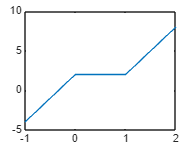

plot(x,h) % shows simple plot, no details

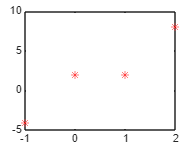

plot(x,h,'r*') % shows simple plot with line style * to mark points of the curve

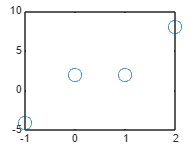

plot(x,h,'o', 'Markersize', 10) % o shows the data points with it size as 10

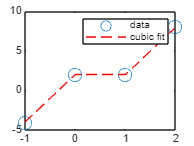

plot(x,y,'o', x, h,'r--', 'Markersize', 10)%x,y,o shows points, x,h,'r--' shows line curve, and then adjust markersize
% Thus, by writing, x, y, sth repeatedly, you can keep adding more features to the curve
legend('data', 'cubic fit') % It labels the feature x,y,o as data and x,h,r-- as cubic fit

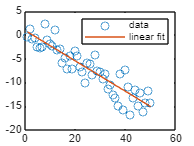



% Fit a polynomial p of degree 1 to the (x,y) data:
        x = 1:50;
        y = -0.3*x + 2*randn(1,50); 
        p = polyfit(x,y,1);
 
      % Evaluate the fitted polynomial p and plot:
        f = polyval(p,x); 
        plot(x,y,'o',x,f,'-') 
        legend('data','linear fit') 

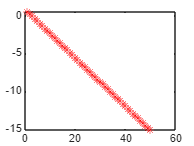

        plot(x,f,'r*') 



% EXERCISE TIPS
% 1, Evaluate a function: Define it and evaluate x = 2:0.01:4, y = f(x)

% 2, Add random noise to the sample: Yn = y + 0.5*randn(size(x)) 
% The randn function generates random number from a normal distribution with mean 0 and standard deviation 1. 
% The 0.5 is a scaling factor that controls the amount of noise added. 

% 3, Plot the noisy signal with marker o
% plot(x, Yn, 'o') This is the plot and the marker is 'o'. 

% Adding colour to the code curves and plotting. Redefine xplot and yplot to avoid overwriting
%xplot=x
%yplot=polyval(Z, x)
% plot(x, yn, '.', 'color','green')



% EXERCISE: POLYNOMIAL FITTING 
% Evaluate y = x^2 for x = -4:0.01:4
x = -4:0.01:4 

x =    -4.0000   -3.9900   -3.9800   -3.9700   -3.9600   -3.9500   -3.9400   -3.9300   -3.9200   -3.9100   -3.9000   -3.8900   -3.8800   -3.8700   -3.8600   -3.8500   -3.8400   -3.8300   -3.8200   -3.8100   -3.8000   -3.7900   -3.7800   -3.7700   -3.7600   -3.7500   -3.7400   -3.7300   -3.7200   -3.7100   -3.7000   -3.6900   -3.6800   -3.6700   -3.6600   -3.6500   -3.6400   -3.6300   -3.6200   -3.6100   -3.6000   -3.5900   -3.5800   -3.5700   -3.5600   -3.5500   -3.5400   -3.5300   -3.5200   -3.5100


y= x.^2 % Use element-wise power 

y =    16.0000   15.9201   15.8404   15.7609   15.6816   15.6025   15.5236   15.4449   15.3664   15.2881   15.2100   15.1321   15.0544   14.9769   14.8996   14.8225   14.7456   14.6689   14.5924   14.5161   14.4400   14.3641   14.2884   14.2129   14.1376   14.0625   13.9876   13.9129   13.8384   13.7641   13.6900   13.6161   13.5424   13.4689   13.3956   13.3225   13.2496   13.1769   13.1044   13.0321   12.9600   12.8881   12.8164   12.7449   12.6736   12.6025   12.5316   12.4609   12.3904   12.3201


size(x)

ans =      1   801


% Add random noise to the sample. Plot the noisy signal with .markers
yn = y + 0.5*randn(1,801) % or use yn = y + randn(size(x)) 

yn =    16.6195   15.9529   15.5002   16.0177   15.7084   16.6676   15.1138   15.4944   14.6355   16.1016   15.5402   15.8407   14.9278   15.2021   15.5503   14.6758   15.0302   13.9661   14.4458   14.4563   14.0900   13.5756   14.4322   14.3330   14.4488   14.5468   13.5503   14.0440   13.9109   14.3629   14.1524   13.2242   12.6349   13.0630   13.8901   13.3188   13.1477   12.8285   12.7919   13.2637   13.3391   13.1413   12.9064   13.3294   12.5834   12.5944   12.0418   12.5612   12.3167   11.8102


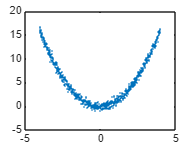

plot(x, yn, '.', 'Markersize', 3) % After adding marker, add the markersize for professionalism 


% Fit a second-degree polynomial to the noisy data 
Z = polyfit(x, yn, 2) % Z is the polynomial eqn that defines the data i.e 1x^2 after random noise added

Z =     1.0016    0.0070   -0.0166



% Plot the fitted polynomial on the same plot, using the same x value and a red line
xplot=x

xplot =    -4.0000   -3.9900   -3.9800   -3.9700   -3.9600   -3.9500   -3.9400   -3.9300   -3.9200   -3.9100   -3.9000   -3.8900   -3.8800   -3.8700   -3.8600   -3.8500   -3.8400   -3.8300   -3.8200   -3.8100   -3.8000   -3.7900   -3.7800   -3.7700   -3.7600   -3.7500   -3.7400   -3.7300   -3.7200   -3.7100   -3.7000   -3.6900   -3.6800   -3.6700   -3.6600   -3.6500   -3.6400   -3.6300   -3.6200   -3.6100   -3.6000   -3.5900   -3.5800   -3.5700   -3.5600   -3.5500   -3.5400   -3.5300   -3.5200   -3.5100


yplot=polyval(Z, x) % Instead of saying yn and overwriting yn

yplot =    15.9816   15.9016   15.8218   15.7423   15.6629   15.5838   15.5048   15.4260   15.3475   15.2691   15.1910   15.1130   15.0352   14.9577   14.8803   14.8032   14.7262   14.6495   14.5729   14.4966   14.4204   14.3444   14.2687   14.1931   14.1178   14.0426   13.9677   13.8929   13.8184   13.7440   13.6699   13.5959   13.5222   13.4486   13.3753   13.3021   13.2292   13.1564   13.0839   13.0115   12.9394   12.8674   12.7957   12.7241   12.6528   12.5816   12.5107   12.4400   12.3694   12.2991


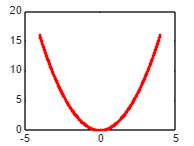

Error using legend (line 169)
Handle inputs of type double cannot be used with this function.

plot(xplot, yplot, '.', 'color','red') % Note the spelling